## Import Data

clear all;
clc;
data = readtable("step_multiple_15V_75ohm.csv");
data = fillmissing(data,'nearest');
data([1,2],:) = [];
% Step info
step_bot=75;
step_top=80;

## Assign Variables

% Seperate values
t = table2array(data(:,1))+5;
ADC = round(table2array(data(:,2))/30*1024);
OCR = table2array(data(:,3));
% Match to duty cycle
OCR = round(OCR/5)*(step_top-step_bot)+step_bot;

% Find index before step
idx = find(OCR>75,1,'first')

idx = 24


% Trim data with new index
t = t(idx-5:end);
ADC = ADC(idx-5:end);
OCR = OCR(idx-5:end);

% Reset time and find sampling time
t = t-t(1);
T_s=t(2)-t(1)

T_s = 0.0156

## Plot Real Data

clf;
plot(t,OCR)

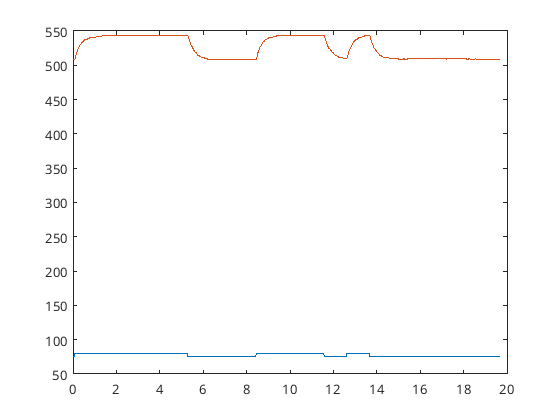

hold on
plot(t,ADC)
hold off

clf

## Identify Transfer Functions

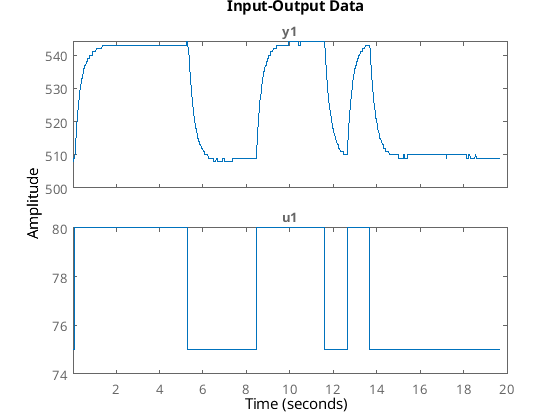

idd = iddata(ADC,OCR,T_s);
plot(idd)

G=tfest(idd,2,0)

G =
 
  From input "u1" to output "y1":
          4122
  ---------------------
  s^2 + 163.7 s + 606.9
 
Continuous-time identified transfer function.

Parameterization:
   Number of poles: 2   Number of zeros: 0
   Number of free coefficients: 3
   Use "tfdata", "getpvec", "getcov" for parameters and their uncertainties.

Status:                                         
Estimated using TFEST on time domain data "idd".
Fit to estimation data: 96.05%                  
FPE: 0.3826, MSE: 0.3795                        


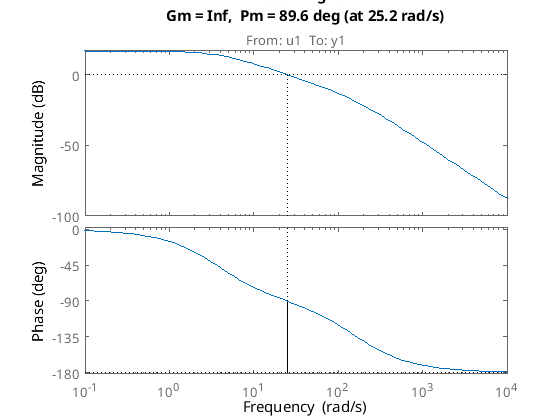

margin(G)

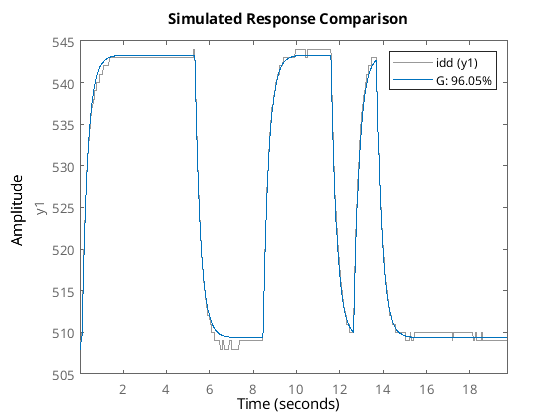

compare(idd,G)  % Passer meget godt med dataet

## Create PID Controller

format long
abs(pole(G))

ans = 1.0e+02 *

   1.599132933691860
   0.037953676139054


gm = 60; Ni=0.7; alpha=1;
% First PID Controller
[wc, Kp, taui,taud, ok] = findpid(G, gm, Ni,alpha)

ans = 'Found 1 valid solution(s) out of 1 phase crossing(s)'

wc =    7.287339268059741


Kp =    0.182988032300996


taui =    0.096057007125781


taud =    0.137224295893973


ok =      1


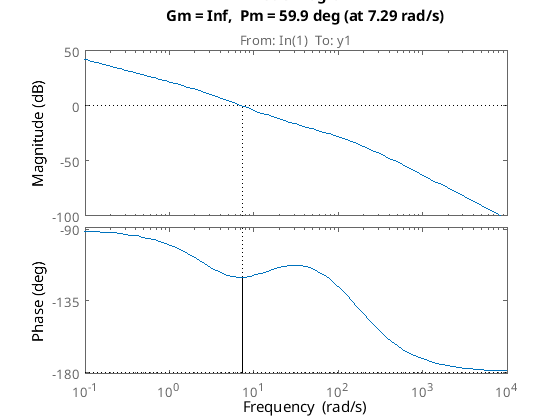

s=tf('s');
Cpid=minreal(Kp*(taui*s+1)/(taui*s)*(taud*s+1)/(alpha*taud*s+1));
Gol=minreal(G*Cpid);
margin(Gol);

Ni = 5

Ni =      5


% Create extra integrator
[wc2, Kp2, taui2, ok] = findpi(Gol, gm, Ni)

ans = 'Found 1 valid solution(s) out of 1 phase crossing(s)'

wc2 =    2.162866991425549


Kp2 =    0.184751085924124


taui2 =    2.311746408735237


ok =      1


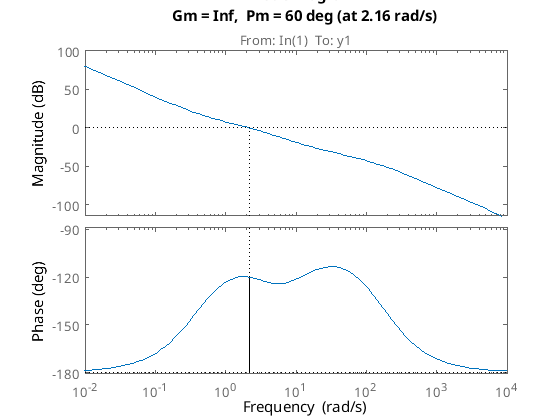

Cpi2=minreal(Kp2*(taui2*s+1)/(taui2*s));
Gol2=minreal(Gol*Cpi2);
margin(Gol2)

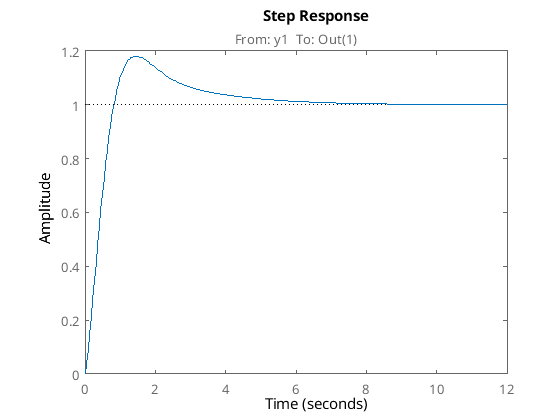


Gcl=minreal(Gol2/(1+Gol2));
step(1*Gcl);

## Z-Transform and Output

Controller=minreal(Cpid*Cpi2)

Controller =
 
  0.03381 s^2 + 0.3666 s + 0.1522
  -------------------------------
                s^2
 
Continuous-time transfer function.



format long
Gz=c2d(Cpid,1/10e3,'tustin');
Gz.Variable= 'z^-1'

Gz =
 
  0.1831 - 0.1829 z^-1
  --------------------
        1 - z^-1
 
Sample time: 0.0001 seconds
Discrete-time transfer function.



[num, den] = tfdata(Gz, 'v');

format long
% Open the file for writing
fileID = fopen('../Code/PID Controller/lib/Controllers/Data.h', 'w');

% Write the array declaration to the file
fprintf(fileID, 'double num[%d] = {',length(num));

% Write each element of the array to the file
for i = 1:length(num)
    fprintf(fileID, '%0.16f', num(i));
    
    % Add a comma after each element except the last one
    if i < length(num)
        fprintf(fileID, ', ');
    end
end

% Complete the array declaration
fprintf(fileID, '};\n');

% Write the array declaration to the file
fprintf(fileID, 'double den[%d] = {',length(den));

% Write each element of the array to the file
for i = 1:length(num)
    fprintf(fileID, '%0.16f', den(i));
    
    % Add a comma after each element except the last one
    if i < length(den)
        fprintf(fileID, ', ');
    end
end

% Complete the array declaration
fprintf(fileID, '};\n');

% Close the file
fclose(fileID);
